# **MATLAB Kursu**

*HAZIRLAYAN: BURAK ÖZPOYRAZ - burakozpoyraz@gmail.com*

## DERS - 3

### 1) KOŞULLAR

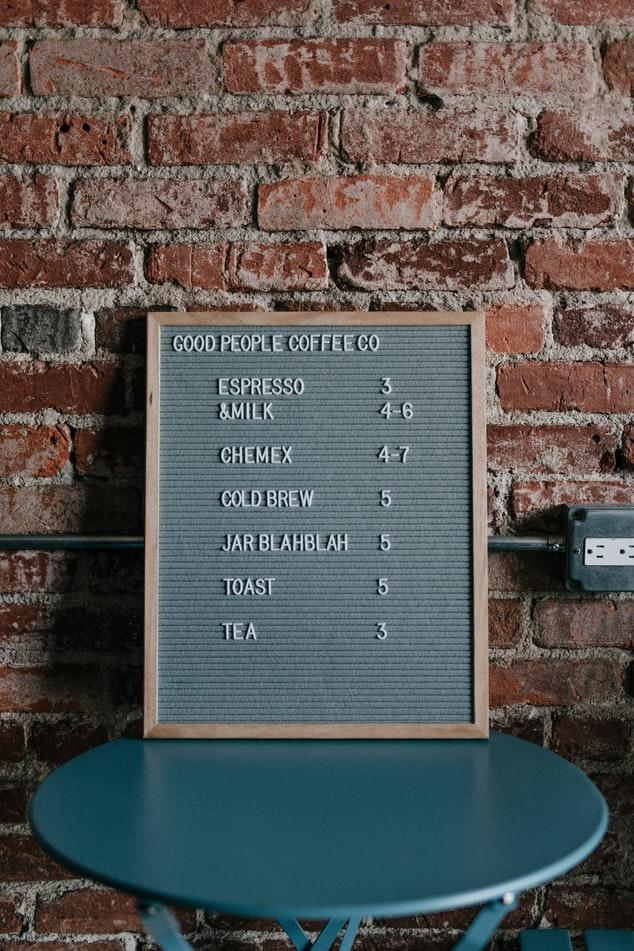

Koşullu işlemler (Conditional Execution), programın bir takım değişkenlere bağlı olarak farklı bir biçimde ilerlemesi anlamına gelir. Yukarıdaki görseldeki örneği inceleyecek olursak, müşterinin ödeyeceği hesap aldığı ürüne göre değişiklik gösterir. Yani burada koşullar devreye girer. Koşullu işlemlerin çalışma prensibi aşağıdaki gibidir:

Müşteri **eğer (if) espresso içerse (expression)**

- $3 ödeme yapacak. (statement)

**Yok eğer (else if) cold brew içerse (expression)**

- $5 ödeme yapacak. (statement)

**Yok eğer hiçbiri değilse (else)**

- Ödeme yapmayacak. (statement)

#### 1.1) If / Else Yapısı

drink = "espresso";
if drink == "espresso"
    check = 3;
elseif drink == "cold brew"
    check = 5;
else
    check = 0;
end

Koşullar (expression) karşılaştırmalardan (relational operators) veya mantık işlemlerinden (logical operators) meydana gelir. Bu işlemlerin hepsi sonucunda doğru (true, 1) ya da yanlış (false, 0) sonuç döndürür. Bu sonuçlara göre de gerçekleşecek olan işlem belirlenir.

**Relational Operations**

a = 6;
b = 5;
if a < b
    result1 = "a is less than b";
elseif a == b
    result1 = "a equals to b";
else
    result1 = "a is greater than b";
end

c = 4;
d = 7;
if c <= d
    result2 = "c is less than or equal to d";
elseif c ~= d
    result2 = "c does not equal to d";
end

**Logical Operations**

time = 1;
money = 0;
energy = 1;
if time && ~money && energy
    person = "young";
elseif ~time && money && energy
    person = "working adult";
elseif time && money && ~energy
    person = "old";
elseif time && ~money && ~energy
    person = "pity";
end

bit1 = 0;
bit2 = 1;
if xor(bit1, bit2)
    result3 = 1;
elseif bit1 || bit2
    result3 = 2;
else
    result3 = 3;
end

İç içe koşullu ifadeler tanımlanabilir.

a = -2;
if a < 0
    if abs(a) < 3
        a_range = "-3 < a < 0";
    elseif abs(a) == 3
        a_range = "a = -3";
    else
        a_range = "a < -3";
    end
elseif a == 0
    a_range = "a = 0";
else
    if abs(a) < 7
        a_range = "0 < a < 7";
    elseif abs(a) == 7
        a_range = "a = 7";
    else
        a_range = "a > 7";
    end
end

#### 1.2) Switch / Case Yapısı

team = "Arsenal";
switch team
    case "Arsenal"
        nickname = "Gunnners";
    case "Manchester United"
        nickname = "Red-Devils";
    case "Manchester City"
        nickname = "Citizens";
    case "West Ham"
        nickname = "Hammers";
    otherwise
        nickname = "unknown";
end

### 2) DÖNGÜLER

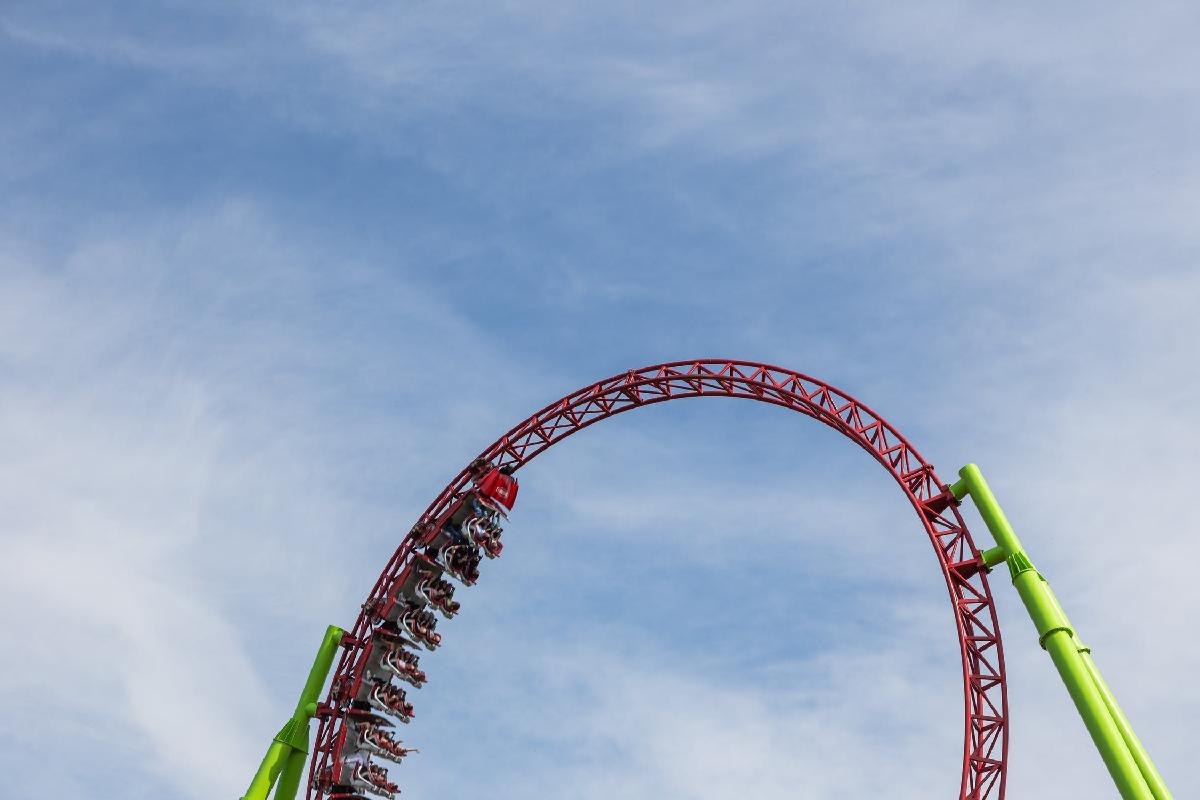

Döngüler bir takım kodların tekrar tekrar çalıştırılması anlamına gelir. Bir döngünün ne kadar devam edeceği iki şekilde belirlenebilir:

- Eğer döngünün kaç defa çalışacağı biliniyorsa, döngü o **sayı için (for)** çalıştırılır.

- Eğer döngünün kaç defa çalıştırılacağı bilinmiyor ancak herhangi bir koşul sağlandıkça devam edeceği biliniyorsa, döngü o koşul sağlanmayana kadar, başka bir deyişle o koşul **sağlandığı sürece (while)** çalıştırılır.

Döngüler çok kullanışlı olsalar da bazı noktalarda süre açısından çok verimsiz olabiliyorlar. Bu durumda döngülerin yapacağı iş daha basit ve verimli matris işlemleri ile gerçekleştirilmelidir.

#### 2.1) For Döngüsü

Eğer döngünün kaç defa çalıştırılacağı biliniyorsa, for döngüleri kullanılır.

sum_val = 0;
for i = 1 : 10
    sum_val = sum_val + i;
end

vector = [1 2 3 4 5 6 7 8 9 10];
vector_sum = 0;
for i = 1 : length(vector)
    vector_sum = vector_sum + vector(i);
end
vector_avg = vector_sum / length(vector);

Bir döngü yerine bir matris işlemi kullanmanın ne kadar avantajlı olacağını analiz edelim.

long_vector = 1 : 1e8;

tic
long_vector_sum = 0;
for i = 1 : length(long_vector)
    long_vector_sum = long_vector_sum + long_vector(i);
end
long_vector_avg = long_vector_sum / length(long_vector);
toc

tic
long_vector_avg2 = mean(long_vector);
toc

Eğer bu işlemi toplamda 1 milyon defa yapmamız gerekirse döngü ve diğer işlem arasındaki süre farkı aşağıdaki gibi olur.

time_loop = 1e6 * x / (3600 * 24);
time_mean = 1e6 * x / (3600 * 24);

Döngü indisinin alacağı değerler aralıklı olarak belirlenebilir.

odd_sum = 0;
for j = 1 : 2 : 100
    odd_sum = odd_sum + j;
end

Döngü içerisinde döngüler tanımlanabilir.

A = [1 2 3 4 5;
     6 7 8 9 10];
A_size = size(A);
row_num = A_size(1);
col_num = A_size(2);
A_sum = 0;
for row_index = 1 : row_num
    for col_index = 1 : col_num
        A_sum = A_sum + A(row_index, col_index);
    end
end

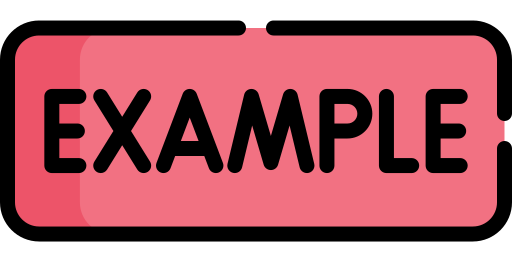

1 ile 100 arasında rastgele tam sayılardan meydana gelen 4x4 boyutunda bir matris üretiniz. Daha sonra, bu matrisi inceleyerek aşağıdaki koşulları sağlayacak yeni bir matris üretiniz.

- Sol köşegendeki elemanlar, yeni matristeki köşegenlere toplanarak eklenecektir.

- Sağ köşegendeki elemanlar, yeni matristeki köşegenlere sırayla toplanarak ve çıkartılarak eklenecektir.

- Diğer elemanlardan 50'den küçük veya 50'ye eşit olanlar için yeni matriste aynı yere -2, 50'den büyük olanlar için de yeni matriste aynı yere 102 konulacaktır.

Rastgele oluşturulan bir matristen yukarıdaki koşulları sağlayarak yeni matris oluşturmaya bir örnek aşağıda verilmiştir:


$$\matrix{
\matrix{
2 & 16 & 34 & 5 \cr
16 & 84 & 93 & 22 \cr
41 & 78 & 98 & 53 \cr
7 & 36 & 62 & 85
}
&
\rightarrow 
&
\matrix{
2 & -2 & -2 & 5 \cr
-2 & 86 & -88 & -2 \cr
-2 & -10 & 184 & 102 \cr
-17 & -2 & 102 & 269
}
}$$


M = randi([1, 100], [4, 4]);
N = zeros(4, 4);
left_diag_sum = 0;
right_diag_sum = 0;
for row_index = 1 : 4
    for col_index = 1 : 4
        m = M(row_index, col_index);
        if row_index == col_index
            left_diag_sum = left_diag_sum + m;
            N(row_index, col_index) = left_diag_sum;
        elseif row_index + col_index == 5
            sign_val = sign(mod(row_index, 2) - 0.5);
            right_diag_sum = right_diag_sum + sign_val * m;
            N(row_index, col_index) = right_diag_sum;
        elseif m <= 50
            N(row_index, col_index) = -2;
        else
            N(row_index, col_index) = 102;
        end
    end
end

#### 2.2) While Döngüsü

Eğer döngünün kaç defa çalıştırılacağı bilinmiyor ancak bir koşul sağlandığı durumda duracağı biliniyorsa while döngüleri kullanılır.

a = 0;
while a < 10
    a = a + 1;
end

rand_vector = randi([1, 9], 1, 7);
index = 1;
element = rand_vector(index);
fprintf("%d\n", element);
while element < 5 && index < length(rand_vector)
    index = index + 1;
    element = rand_vector(index);
    fprintf("%d\n", element);
end

 

### **3) PROBLEM / BİLDİK Mİ?**

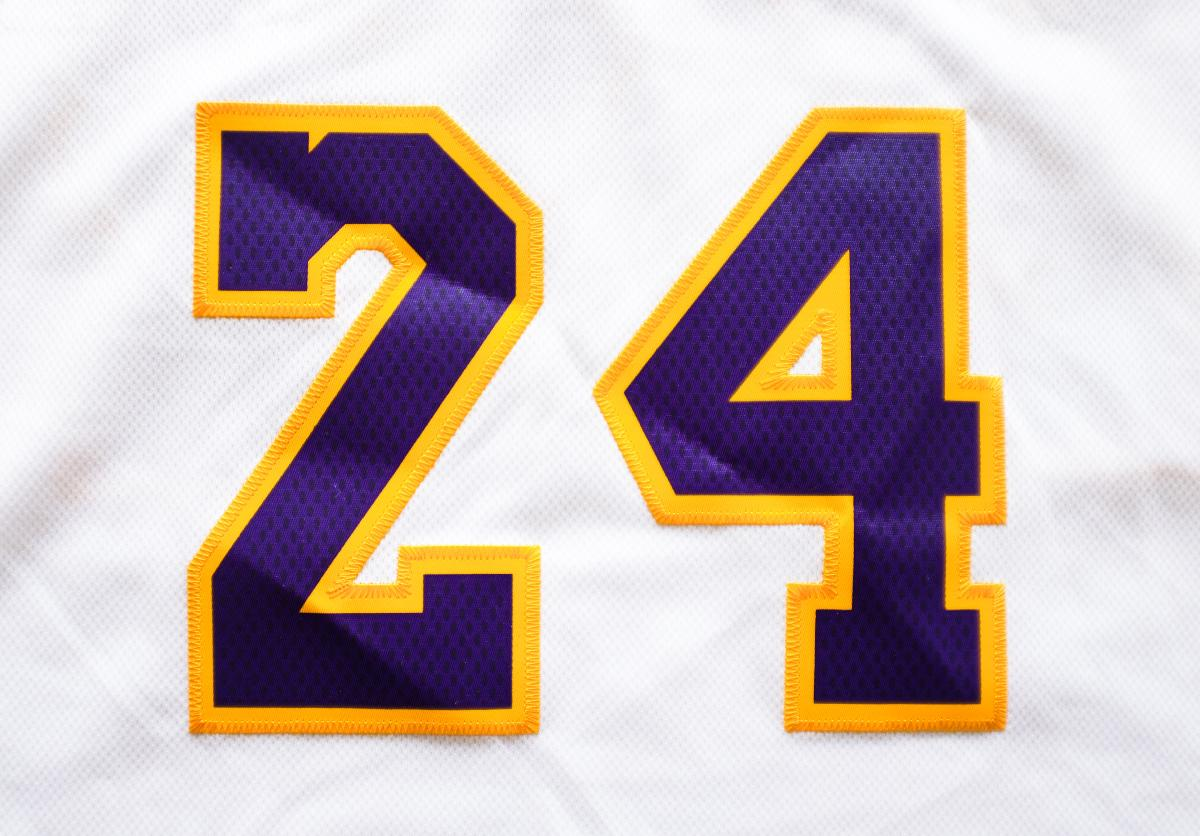

Bir sayı tahmin oyunu programlayacağız. Bunun için, bilgisayar tarafından 1 ile 1'den büyük bir sayı ($x$) arasından rastgele bir tam sayı alacak ve bu sayıyı tahmin etmeye çalışacağız. Oyunda olmasını istediğimiz özellikleri aşağıdaki gibi sıralayabiliriz:

- Her tahminden sonra bilgisayar bize tahminimizin gerçek sayıdan büyük ya da küçük olduğu bilgisini vermelidir.

- Maksimum tahmin sayısı için limit ($L$) olacaktır.

- Verilen tahmin limiti kadar ya da limitten daha az sayıda tahmin yaparak sayıyı bilebilirsek oyunu kazanmış yoksa kaybetmiş olacağız.

- Her oyun bittiğinde program bize tekrar oynamak isteyip istemediğimizi sormalıdır ve biz istedikçe yeni oyun başlamalıdır.

- Yeni oyun istemediğimizde program durmalı ve bize oynadığımız tüm oyunların sayısını, galibiyet sayımızı ve mağlubiyet sayımızı göstermelidir.

- Oyunda farklı zorluk seviyeleri olacaktır:

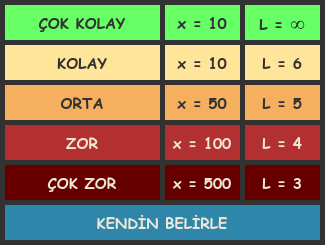

new_game = 1;
num_game = 0;
num_win = 0;
num_lose = 0;
while new_game == 1
    difficulty = -1;
    while difficulty < 0 || difficulty > 5
        difficulty = input("Lütfen 1 ile 5 arasında bir zorluk seviyesi "...
          + "seçiniz, kendi zorluk seviyenizi seçmek için 0 tuşlayınız: ");
    end
    
    if difficulty == 0
        x = -1;
        while x < 2
            x = input("Lütfen tahmin edeceğiniz sayının üst limiti için"...
                + "1'den büyük bir sayı giriniz: ");
        end
        
        L = -1;
        while L < 0
            L = input("Lütfen maksimum tahmin sayınızı 1'den büyük bir sayı"...
                + "olarak seçiniz, eğer limit koymak istemiyorsanız 0 seçiniz: ");
        end
    elseif difficulty == 1
        x = 10;
        L = 1e6;
    elseif difficulty == 2
        x = 10;
        L = 6;
    elseif difficulty == 3
        x = 50;
        L = 5;
    elseif difficulty == 4
        x = 100;
        L = 4;
    else
        x = 500;
        L = 3;
    end
    
    rand_int = randi([1, x], [1, 1]);
    guess_count = 1;
    true_guess = 0;
    while guess_count <= L && true_guess == 0
        guess = input("Lütfen bir tahmin yapınız: ");
        if guess == rand_int
            true_guess = 1;
            fprintf("Doğru bildiniz!!!\n");
        elseif guess < rand_int
            fprintf("Bilemediniz :( Daha büyük bir sayı " +...
                    "tahmin etmeniz gerekiyor.\n");
        else
            fprintf("Bilemediniz :( Daha küçük bir sayı " +...
                    "tahmin etmeniz gerekiyor.\n");
        end
        guess_count = guess_count + 1;
    end
    
    num_game = num_game + 1;
    if true_guess == 0
        num_lose = num_lose + 1;
        fprintf("Oyunu kaybettiniz :((\n");
    else
        num_win = num_win + 1;
    end
    
    new_game = -1;
    while new_game ~= 0 && new_game ~= 1
        new_game = input("Yeniden oynamak istiyorsanız 1" +...
                   ", istemiyorsanız 0 tuşlayın: ");
    end
end
fprintf("Toplam oynadığınız oyun sayısı: %d\n", num_game);
fprintf("Toplam kazandığınız oyun sayısı: %d\n", num_win);
fprintf("Toplam kaybettiğiniz oyun sayısı: %d\n", num_lose);